%% Audio Playback with Enhanced Audio
% This script includes noise removal and audio enhancement

% Read the audio file (replace 'sample.wav' with your audio file)
[y, Fs] = audioread('output.wav');

% Convert stereo to mono if necessary
if size(y, 2) > 1
    y = mean(y, 2);  % Convert to mono by averaging channels
end

% Play original audio
disp('Playing original audio...');

Playing original audio...


sound(y, Fs);
pause(length(y)/Fs + 1);

% Add Rayleigh noise
noise = raylrnd(0.1, size(y));
noisy_audio = y + noise;

% Play noisy audio
disp('Playing audio with Rayleigh noise...');

Playing audio with Rayleigh noise...


sound(noisy_audio, Fs);
pause(length(y)/Fs + 1);

% Wavelet denoising
filtered_audio = wdenoise(noisy_audio, 5, 'Wavelet', 'sym8');

% Amplify the denoised audio
amplification = 2;  % Increase this value to make it louder
filtered_audio = filtered_audio * amplification;

% Change pitch (increase sampling rate for higher pitch)
pitch_factor = 1.2;  % > 1 for higher pitch, < 1 for lower pitch
new_Fs = Fs * pitch_factor;

% Play enhanced audio
disp('Playing enhanced audio...');

Playing enhanced audio...


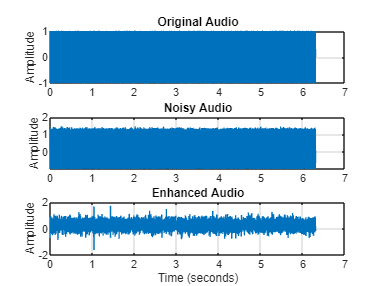

sound(filtered_audio, new_Fs);

% Plot results
t = (0:length(y)-1)/Fs;

subplot(3,1,1);
plot(t, y);
title('Original Audio');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, noisy_audio);
title('Noisy Audio');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t, filtered_audio);
title('Enhanced Audio');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;